## Question 4

warning off; close all; clc

### >>> 4.0 - Data Read and Split

load HW4_Q4.mat

sys_1_data = Z;
sys_2_data = Z2;

data_length = length(sys_1_data.u);

sys_1_iden_data = sys_1_data(1:data_length/2);
sys_1_val_data = sys_1_data(data_length/2+1:end);

sys_2_iden_data = sys_2_data(1:data_length/2);
sys_2_val_data = sys_2_data(data_length/2+1:end);



sys_1_iden_u = sys_1_iden_data.u;
sys_1_iden_y = sys_1_iden_data.y;

sys_1_val_u = sys_1_val_data.u;
sys_1_val_y = sys_1_val_data.y;


sys_2_iden_u = sys_2_iden_data.u;
sys_2_iden_y = sys_2_iden_data.y;

sys_2_val_u = sys_2_val_data.u;
sys_2_val_y = sys_2_val_data.y;

### >>> 4.1 - Reducing the Average to Zero

threshold = 10e-4; % = 0.001

if mean(sys_1_iden_u) > threshold
    sys_1_iden_u = detrend(sys_1_iden_u);
    sys_1_iden_y = detrend(sys_1_iden_y);
end

if mean(sys_2_iden_u) > threshold
    sys_2_iden_u = detrend(sys_2_iden_u);
    sys_2_iden_y = detrend(sys_2_iden_y);
end

### >>> 4.2 - ARX for system 1 & 2

####          4.2.1 ARX - system 1

N = length(sys_1_iden_u);
fprintf("====================Degree Extraction System 1========================\n")

====================Degree Extraction System 1========================


progress = 0.001;
prev_r2 = 0;
for degree=1:1:15
    na = degree;
    nb = degree;
    p = na + nb;

    U = arx_U_builder(na,nb,sys_1_iden_u,sys_1_iden_y);

    sys_1_theta_hat = inv(U'*U)*U'*sys_1_iden_y;
    y_hat = U*sys_1_theta_hat;
    
    t = (sys_1_iden_data.Tstart:sys_1_iden_data.Ts:N*sys_1_iden_data.Tstart);

    r2_arx = rSQR(sys_1_iden_y, y_hat);
    
    fprintf(">>> Degree = %d : R2=%f\n", degree, r2_arx)

    if (r2_arx-prev_r2)>progress
        prev_r2 = r2_arx;
    else
        fprintf("-------------------------------------------------------------\n")
        fprintf("Since the improvement of R2 metric value is less than %.4f,\nthe proper degree of the system is obtained as %d .\n", progress, degree)
        break;
    end
    fprintf("-------------------------------------------------------------\n")
end

>>> Degree = 1 : R2=0.377767


-------------------------------------------------------------


>>> Degree = 2 : R2=0.891014


-------------------------------------------------------------


>>> Degree = 3 : R2=0.908740


-------------------------------------------------------------


>>> Degree = 4 : R2=0.910575


-------------------------------------------------------------


>>> Degree = 5 : R2=0.911021


-------------------------------------------------------------


Since the improvement of R2 metric value is less than 0.0010,
the proper degree of the system is obtained as 5 .


fprintf("=================================================================\n")

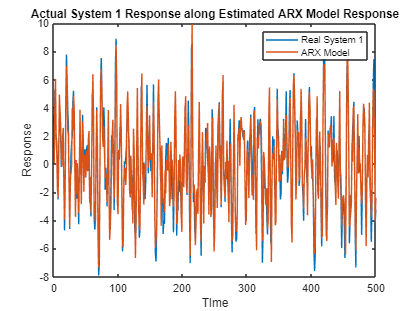

sys_1_degree = degree;
sys_1_na = sys_1_degree;
sys_1_nb = sys_1_degree;
U = arx_U_builder(sys_1_na,sys_1_nb,sys_1_val_u,sys_1_val_y);

sys_1_y_hat = U*sys_1_theta_hat;

t = (sys_1_iden_data.Tstart:sys_1_iden_data.Ts:N*sys_1_iden_data.Tstart);

sys_1_r2_arx = rSQR(sys_1_val_y, sys_1_y_hat);

t = (sys_1_iden_data.Tstart:sys_1_iden_data.Ts:N*sys_1_iden_data.Tstart);
figure(1)
plot(t,sys_1_val_y,t,sys_1_y_hat)
title("Actual System 1 Response along Estimated ARX Model Response")
xlabel("TIme")
ylabel("Response")
legend("Real System 1", "ARX Model")

####          4.2.2 ARX - system 2

N = length(sys_2_iden_u);
fprintf("====================Degree Extraction System 2========================\n")

====================Degree Extraction System 2========================


progress = 0.001;
prev_r2 = 0;
for degree=1:1:15
    na = degree;
    nb = degree;
    p = na + nb;

    U = arx_U_builder(na,nb,sys_2_iden_u,sys_2_iden_y);

    sys_2_theta_hat = inv(U'*U)*U'*sys_2_iden_y;
    y_hat = U*sys_2_theta_hat;
    
    t = (sys_1_iden_data.Tstart:sys_1_iden_data.Ts:N*sys_1_iden_data.Tstart);

    r2_arx = rSQR(sys_2_iden_y, y_hat);
    
    fprintf(">>> Degree = %d : R2=%f\n", degree, r2_arx)

    if (r2_arx-prev_r2)>progress
        prev_r2 = r2_arx;
    else
        fprintf("-------------------------------------------------------------\n")
        fprintf("Since the improvement of R2 metric value is less than %.4f,\nthe proper degree of the system is obtained as %d .\n", progress, degree)
        break;
    end
    fprintf("-------------------------------------------------------------\n")
end

>>> Degree = 1 : R2=0.176378


-------------------------------------------------------------


>>> Degree = 2 : R2=0.748271


-------------------------------------------------------------


>>> Degree = 3 : R2=0.832194


-------------------------------------------------------------


>>> Degree = 4 : R2=0.839945


-------------------------------------------------------------


>>> Degree = 5 : R2=0.853096


-------------------------------------------------------------


>>> Degree = 6 : R2=0.864011


-------------------------------------------------------------


>>> Degree = 7 : R2=0.869402


-------------------------------------------------------------


>>> Degree = 8 : R2=0.869908


-------------------------------------------------------------


Since the improvement of R2 metric value is less than 0.0010,
the proper degree of the system is obtained as 8 .


fprintf("=================================================================\n")

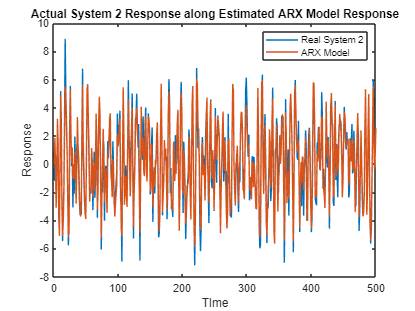

sys_2_degree = degree;
sys_2_na = sys_2_degree;
sys_2_nb = sys_2_degree;
U = arx_U_builder(sys_2_na,sys_2_nb,sys_2_val_u,sys_2_val_y);

sys_2_y_hat = U*sys_2_theta_hat;

t = (sys_2_iden_data.Tstart:sys_2_iden_data.Ts:N*sys_2_iden_data.Tstart);

sys_2_r2_arx = rSQR(sys_2_val_y, sys_2_y_hat);

t = (sys_2_iden_data.Tstart:sys_2_iden_data.Ts:N*sys_2_iden_data.Tstart);
figure(2)
plot(t,sys_2_val_y,t,sys_2_y_hat)
title("Actual System 2 Response along Estimated ARX Model Response")
xlabel("TIme")
ylabel("Response")
legend("Real System 2", "ARX Model")

### >>> 4.3 - ARMAX for system 1 & 2

####          4.3.1 ARMAX - system 1

fprintf("=================================================================\n")

fprintf("=================================================================\n")

sys_1_na = sys_1_degree;
sys_1_nb = sys_1_degree;
sys_1_nk = 1;
sys_1_nc = 0;

data = iddata(sys_1_iden_y, sys_1_iden_u, 1);
sys_1_armaxModel = armax(data, [sys_1_na, sys_1_nb, sys_1_nc, sys_1_nk]);

sys_1_y_hat = sim(sys_1_armaxModel, sys_1_val_u);
fprintf("R2 metric value:\n")

R2 metric value:



sys_1_r2_armax = rSQR(sys_1_val_y, sys_1_y_hat)

sys_1_r2_armax = 0.6646

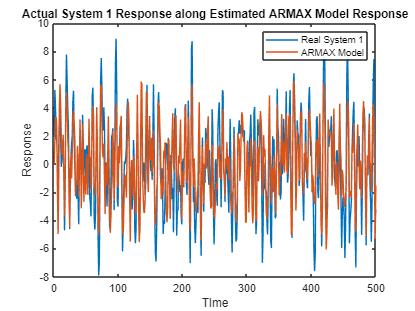


t = (sys_1_iden_data.Tstart:sys_1_iden_data.Ts:N*sys_1_iden_data.Tstart);
figure(3)
plot(t,sys_1_val_y,t,sys_1_y_hat)
title("Actual System 1 Response along Estimated ARMAX Model Response")
xlabel("TIme")
ylabel("Response")
legend("Real System 1", "ARMAX Model")

####          4.3.2 ARMAX - system 2

fprintf("=================================================================\n")

data = iddata(sys_2_iden_y, sys_2_iden_u, 1);
sys_2_na = sys_2_degree;
sys_2_nb = sys_2_degree;
sys_2_nk = 1;
sys_2_nc = 0;

data = iddata(sys_2_iden_y, sys_2_iden_u, 1);
sys_2_armaxModel = armax(data, [sys_2_na, sys_2_nb, sys_2_nc, sys_2_nk]);

sys_2_y_hat = sim(sys_2_armaxModel, sys_2_val_u);
fprintf("R2 metric value:\n")

R2 metric value:


sys_2_r2_armax = rSQR(sys_2_val_y, sys_2_y_hat)

sys_2_r2_armax = 0.8928

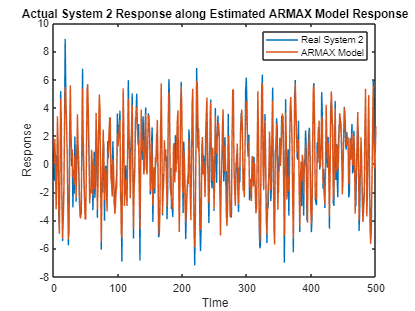



t = (sys_2_iden_data.Tstart:sys_2_iden_data.Ts:N*sys_2_iden_data.Tstart);
figure(4)
plot(t,sys_2_val_y,t,sys_2_y_hat)
title("Actual System 2 Response along Estimated ARMAX Model Response")
xlabel("TIme")
ylabel("Response")
legend("Real System 2", "ARMAX Model")

### >>> 4.4 - Box-Jenkins for system 1 & 2

####          4.4.1 Box-Jenkins - system 1

sys_1_na = sys_1_degree;
sys_1_nb = sys_1_degree;
sys_1_nk = 1;
sys_1_nc = 0;
fprintf("=================================================================\n")

fprintf("=================================================================\n")
data = iddata(sys_1_iden_y, sys_1_iden_u, 1);
sys_1_BJModel = bj(data, [sys_1_na, sys_1_nb, sys_1_nc, 0, sys_1_nk]);


sys_1_y_hat = sim(sys_1_BJModel, sys_1_val_u);
fprintf("R2 metric value:\n")

R2 metric value:


sys_1_r2_bj = rSQR(sys_1_val_y, sys_1_y_hat)

sys_1_r2_bj = 0.6144

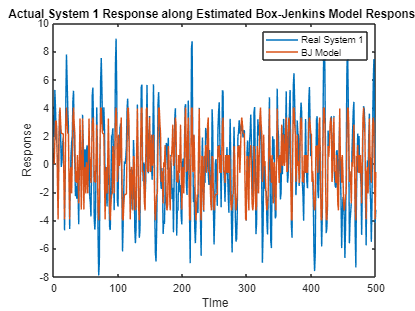


t = (sys_1_iden_data.Tstart:sys_1_iden_data.Ts:N*sys_1_iden_data.Tstart);
figure(5)
plot(t,sys_1_val_y,t,sys_1_y_hat)
title("Actual System 1 Response along Estimated Box-Jenkins Model Response")
xlabel("TIme")
ylabel("Response")
legend("Real System 1", "BJ Model")

####          4.4.2 Box-Jenkins - system 2

sys_2_na = sys_2_degree;
sys_2_nb = sys_2_degree;
sys_2_nk = 1;
sys_2_nc = 0;
fprintf("=================================================================\n")

data = iddata(sys_2_iden_y, sys_2_iden_u, 1);
sys_2_BJModel = bj(data, [sys_2_na, sys_2_nb, sys_2_nc, 0, sys_2_nk]);

sys_2_y_hat = sim(sys_2_BJModel, sys_2_val_u);

fprintf("R2 metric value:\n")

R2 metric value:


sys_2_r2_bj = rSQR(sys_2_val_y, sys_2_y_hat)

sys_2_r2_bj = 0.8872

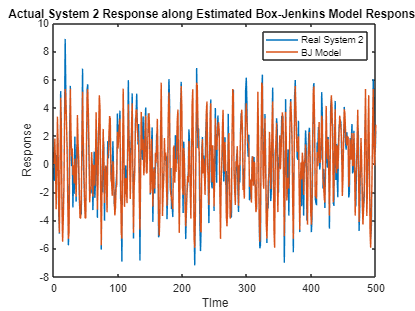


t = (sys_2_iden_data.Tstart:sys_2_iden_data.Ts:N*sys_2_iden_data.Tstart);
figure(6)
plot(t,sys_2_val_y,t,sys_2_y_hat)
title("Actual System 2 Response along Estimated Box-Jenkins Model Response")
xlabel("TIme")
ylabel("Response")
legend("Real System 2", "BJ Model")

### >>> 4.5 - Comparison

>>> System 1:

       ARX R2 = 0.91

       ARMAX R2 = 0.66

       Box-Jenkins R2 = 0.61

>>> System 2:

       ARX R2 = 0.86

       ARMAX R2 = 0.89

       Box-Jenkins R2 = 0.88